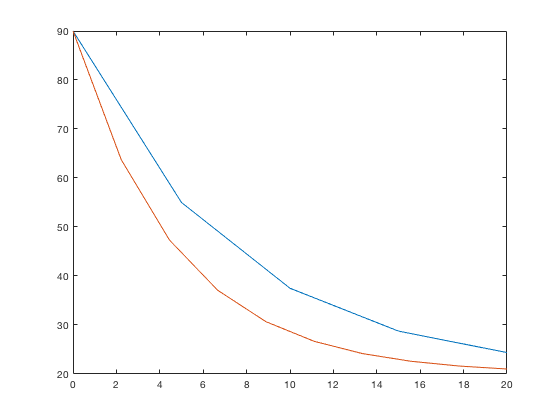

clear all
clc
close all

[x1,t1] = IVP(3);
[x2,t2] = IVP(5);
[x3,t3] = IVP(5);
[x4,t4] = IVP(10);


plot(t3,x3);
hold on
plot(t4,x4);

function [x,t] = IVP(n)
dt = 20/n;
t = linspace(0,20,n);

SOL = NaN(1,length(t));
SOL(1,1) = 90;

for(k = 2:length(t))
    s = -0.25*(SOL(k-1)-20) + -0.25*(SOL(k-1)-20+dt*-0.25*(SOL(k-1)-20));
    SOL(k) = SOL(k-1) + 0.5*dt*s;
end
x = SOL;
end